[g,fs] = audioread("G.wav") ;

x1 = g(:,1)' ;
f1 = fft(x1)/length(x1);
X1 = fftshift(f1);
omega1 = linspace(-fs/2, fs/2, length(X1));
time = 0:1/fs:7;
time = time(1:end-1) ;
phase1 = angle(X1);
magnitude1 = abs(X1);

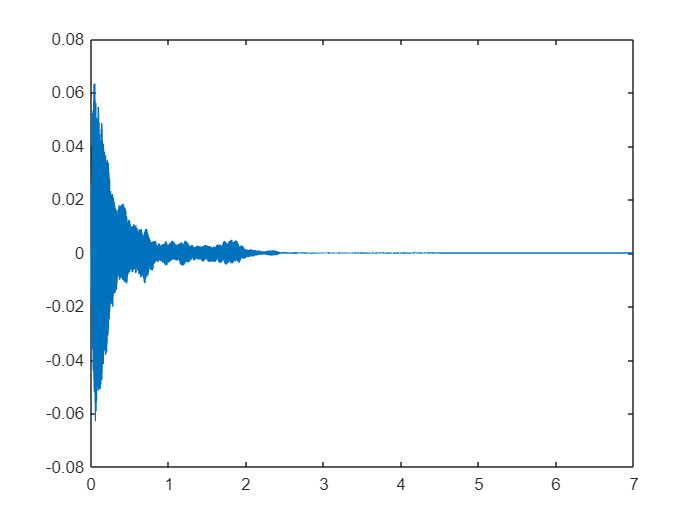

figure
plot(time, x1);

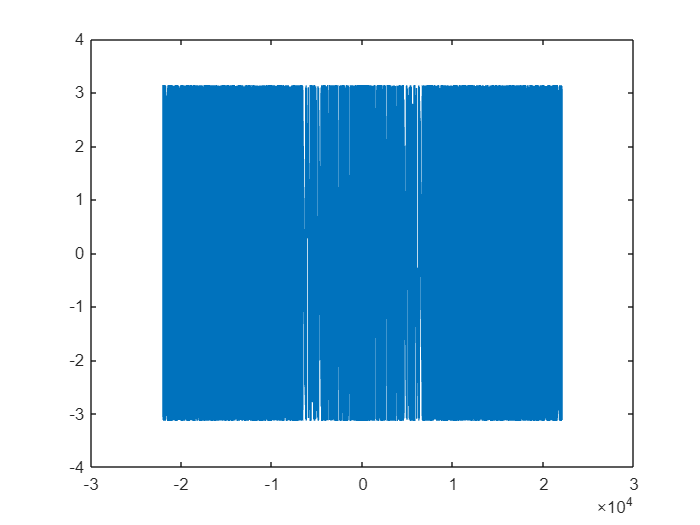

plot(omega1, phase1);

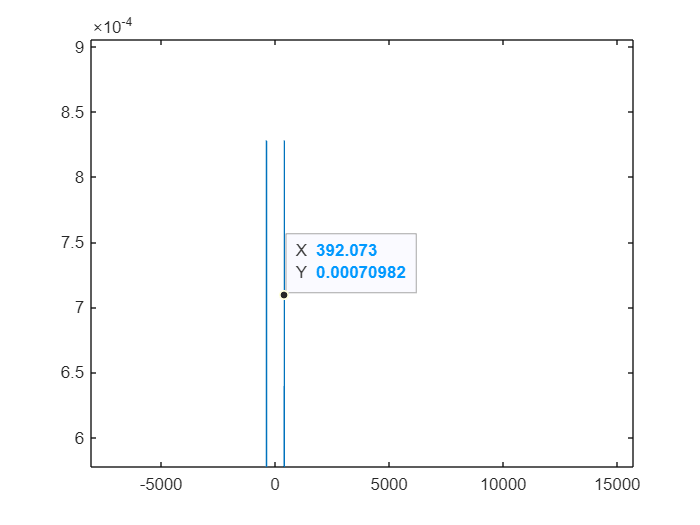

figure
plot(omega1, magnitude1)

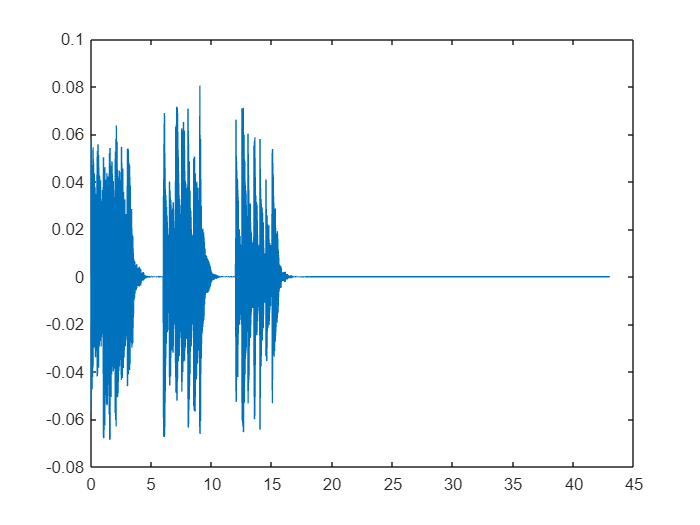

[demo345,Fs] = audioread("Demo345.wav") ;
x345 = demo345(:,1)' ;
f345 = fft(x345)/length(x345);
X345 = fftshift(f345);
omega345 = linspace(-fs/2, fs/2, length(X345));
time = 0:1/fs:length(x345)/Fs;
time = time(1:end-1) ;
phase345 = angle(X345);
magnitude345 = abs(X345);
figure
plot(time, x345);

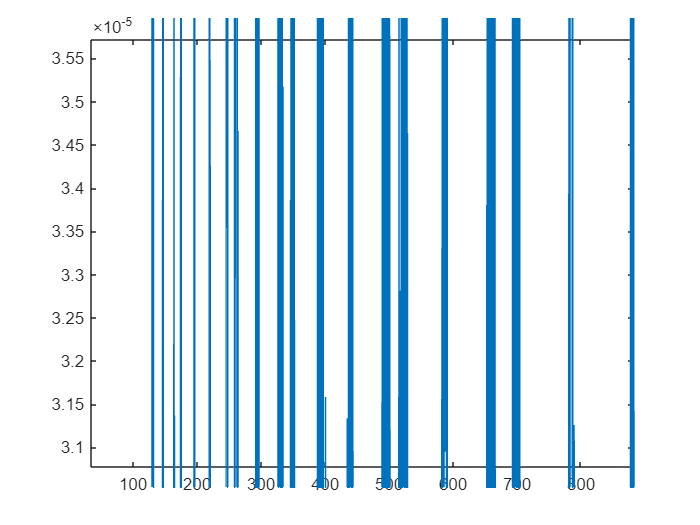

figure
plot(omega345, magnitude345)

revisar los espectros de frecuencia arriba del 2 para la escala 3

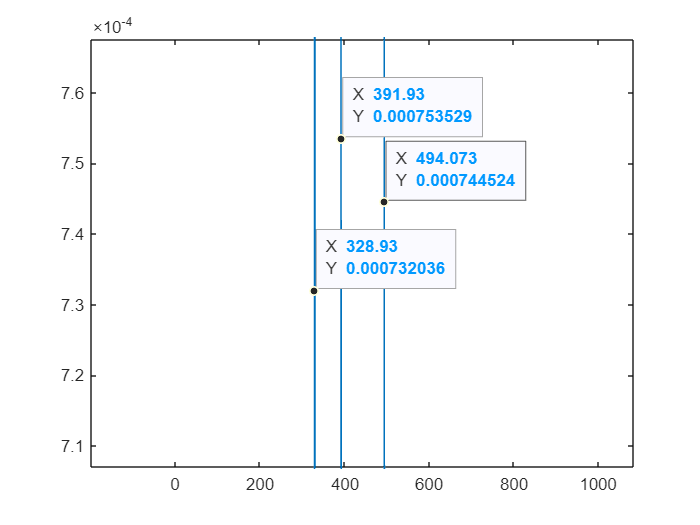

[E,fs] = audioread("E3chord.wav") ;
xE = E(:,1)' ;
fE = fft(xE)/length(xE);
XE = fftshift(fE);
omegaE = linspace(-fs/2, fs/2, length(XE));
time = 0:1/fs:length(xE)/Fs;
time = time(1:end-1) ;
magnitudeE = abs(XE);
figure
plot(omegaE, magnitudeE)

xlim([-199 1084])
ylim([0.0007070 0.0007676])
 
ax = gca;
chart = ax.Children(1);
datatip(chart,494.1,0.0007445);
datatip(chart,391.9,0.0007535);
datatip(chart,328.9,0.000732);

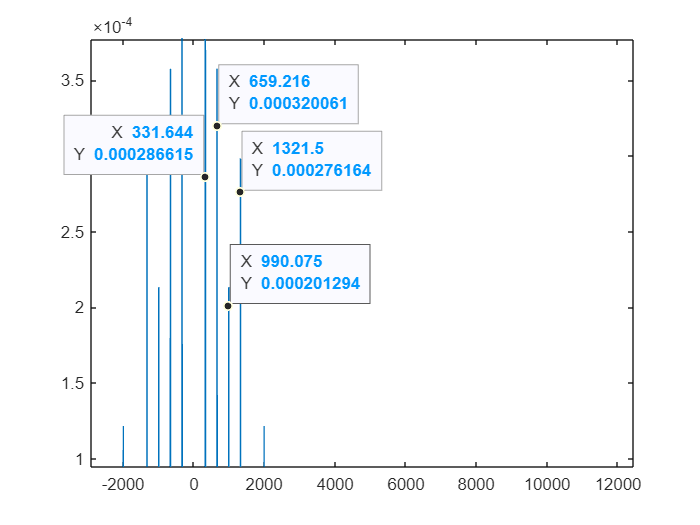

%prueba de una palabra (en)
[W1,fs] = audioread("ratatouille\En.wav") ;
xw1 = W1(:,1)' ;
fw1 = fft(xw1)/length(xw1);
Xw1 = fftshift(fw1);
omegaw1 = linspace(-fs/2, fs/2, length(Xw1));
time = 0:1/fs:length(xw1)/Fs;
time = time(1:end-1) ;
magnitudew1 = abs(Xw1);
figure
plot(omegaw1, magnitudew1)

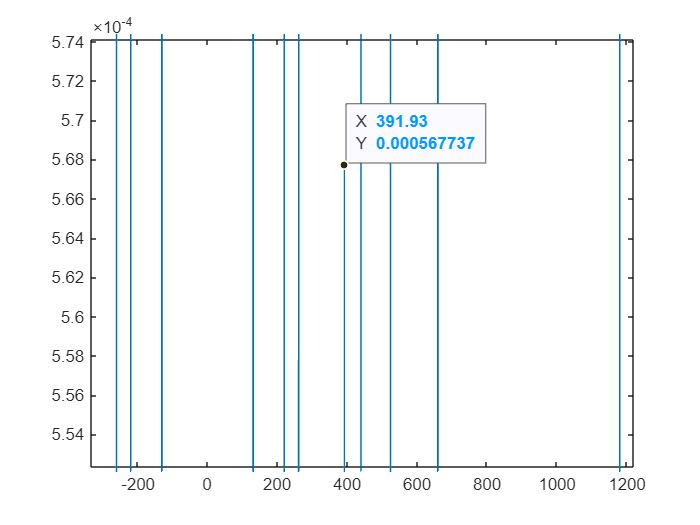

%prueba de una palabra (oculté)
[W2,fs] = audioread("ratatouille\oculte.wav") ;
xw2 = W2(:,1)' ;
fw2 = fft(xw2)/length(xw2);
Xw2 = fftshift(fw2);
omegaw2 = linspace(-fs/2, fs/2, length(Xw2));
time = 0:1/fs:length(xw2)/Fs;
time = time(1:end-1) ;
magnitudew2 = abs(Xw2);
figure
plot(omegaw2, magnitudew2)

xlim([-1771 4929])
ylim([0.000568 0.000680])

ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,131.1,0.0006065,"Location","northwest");
datatip(chart2,219.8,0.0006049,"Location","southwest");
datatip(chart2,261.1,0.0006154);
datatip(chart2,439.8,0.0006565,"Location","northwest");
datatip(chart2,523.6,0.0006533);
datatip(chart2,659.9,0.0006054,"Location","southeast");
datatip(chart2,1180,0.000628);
datatip(chart2,1180,0.0006934);
datatip(chart2,1180,0.0006934); 

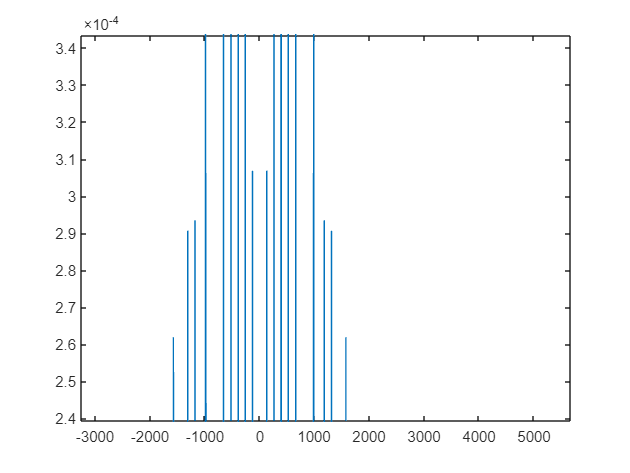

%prueba de una palabra en melodia (oculté)
[W3,fs] = audioread("ratatouille\ocultemelody.wav") ;
xw3 = W3(:,1)' ;
fw3 = fft(xw3)/length(xw3);
Xw3 = fftshift(fw3);
omegaw3 = linspace(-fs/2, fs/2, length(Xw3));
time = 0:1/fs:length(xw3)/fs;
time = time(1:end-1) ;
magnitudew3 = abs(Xw3);
figure
plot(omegaw3, magnitudew3)

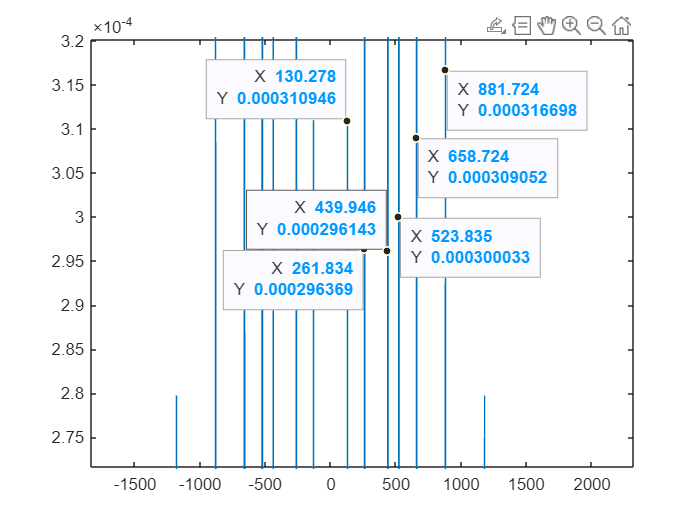

%prueba de una palabra en melodia con silencios (oculté)
[W3,fs] = audioread("ratatouille\ocultesilencio.wav") ;
xw3 = W3(:,1)' ;
fw3 = fft(xw3)/length(xw3);
Xw3 = fftshift(fw3);
omegaw3 = linspace(-fs/2, fs/2, length(Xw3));
time = 0:1/fs:length(xw3)/Fs;
time = time(1:end-1) ;
magnitudew3 = abs(Xw3);
figure
plot(omegaw3, magnitudew3)

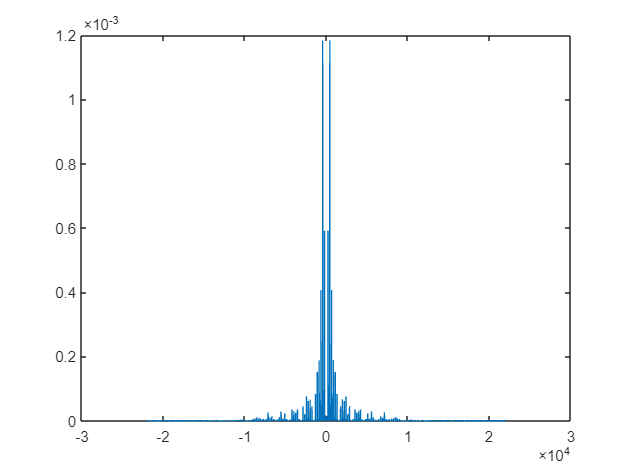

% A3 (L)
[A3,fs] = audioread("A3testGuitar.wav") ;
xa3 = A3(:,1)' ;
fa3 = fft(xa3)/length(xa3);
Xa3 = fftshift(fa3);
omegaa3 = linspace(-fs/2, fs/2, length(Xa3));
time = 0:1/fs:length(xa3)/fs;
time = time(1:end-1) ;
magnitudea3 = abs(Xa3);
figure
plot(omegaa3, magnitudea3)

sound(A3, fs)

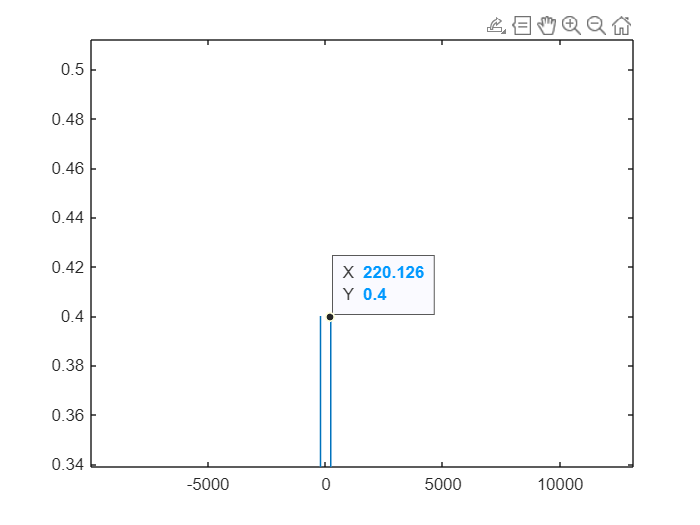

% A3 (L) frequency
[A3,fs] = audioread("A3freq.wav") ;
xa3 = A3(:,1)' ;
fa3 = fft(xa3)/length(xa3);
Xa3 = fftshift(fa3);
omegaa3 = linspace(-fs/2, fs/2, length(Xa3));
time = 0:1/fs:length(xa3)/fs;
time = time(1:end-1) ;
magnitudea3 = abs(Xa3);
figure
plot(omegaa3, magnitudea3)

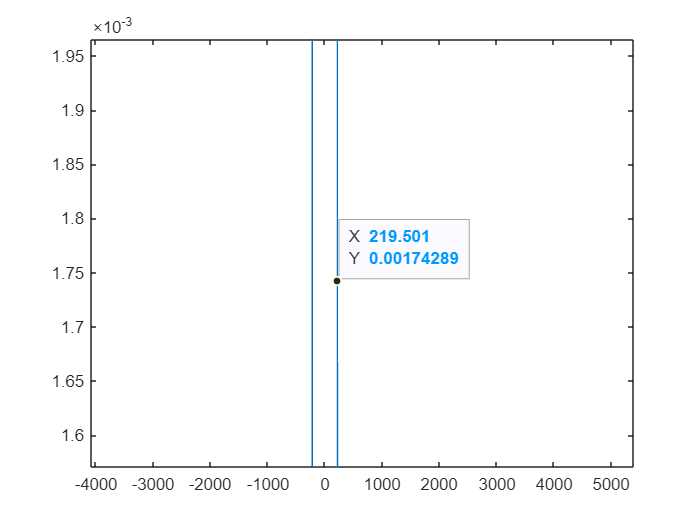

% A3 (L) Classical Guitar Tablature
[A3,fs] = audioread("A3AcousticTest.wav") ;
xa3 = A3(:,1)' ;
fa3 = fft(xa3)/length(xa3);
Xa3 = fftshift(fa3);
omegaa3 = linspace(-fs/2, fs/2, length(Xa3));
time = 0:1/fs:length(xa3)/fs;
time = time(1:end-1) ;
magnitudea3 = abs(Xa3);
figure
plot(omegaa3, magnitudea3)

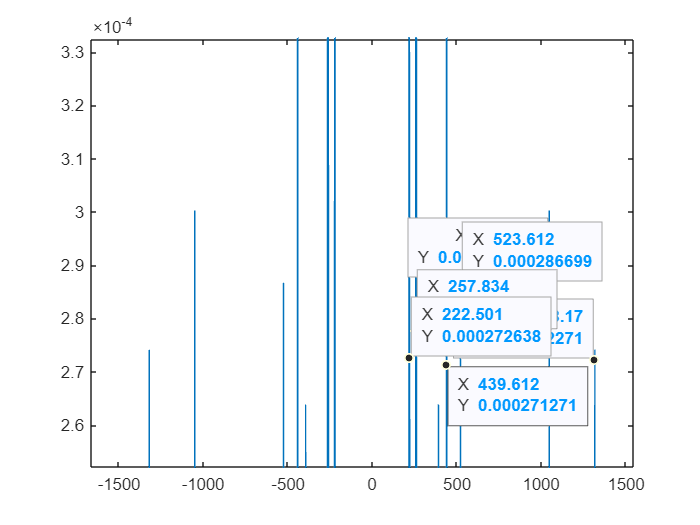

%prueba de una palabra en melodia con guitarra clasica (oculté)
[W3,fs] = audioread("ratatouille\oculteClassic.wav") ;
xw3 = W3(:,1)' ;
fw3 = fft(xw3)/length(xw3);
Xw3 = fftshift(fw3);
omegaw3 = linspace(-fs/2, fs/2, length(Xw3));
time = 0:1/fs:length(xw3)/fs;
time = time(1:end-1) ;
magnitudew3 = abs(Xw3);
figure
plot(omegaw3, magnitudew3)

sound(W3, fs)

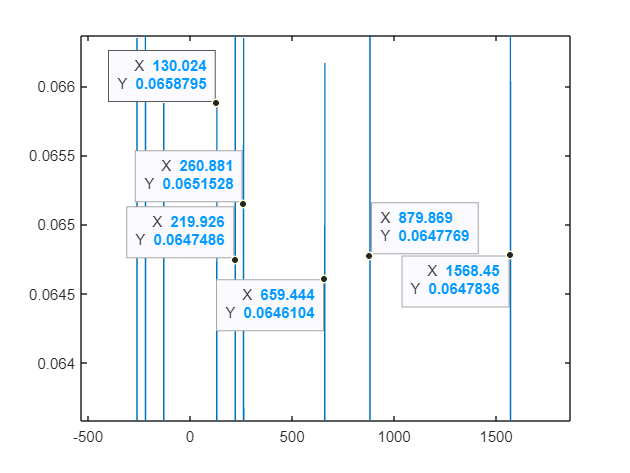

%prueba de una palabra en melodia con frecuencias (oculté)
[W3,fs] = audioread("oculteFreq.wav") ;
xw3 = W3(:,1)' ;
fw3 = fft(xw3)/length(xw3);
Xw3 = fftshift(fw3);
omegaw3 = linspace(-fs/2, fs/2, length(Xw3));
time = 0:1/fs:length(xw3)/fs;
time = time(1:end-1) ;
magnitudew3 = abs(Xw3);
figure
plot(omegaw3, magnitudew3)

xlim([-531 1863])
ylim([0.06358 0.06637])
 
ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,1568,0.06478,"Location","southwest");
datatip(chart3,879.9,0.06478);
datatip(chart3,659.4,0.06461,"Location","southwest");
datatip(chart3,260.9,0.06515,"Location","northwest");
datatip(chart3,219.9,0.06475,"Location","northwest");
datatip(chart3,220.3,0.06653);
datatip(chart3,130,0.06588,"Location","northwest");

sound(W3, fs)

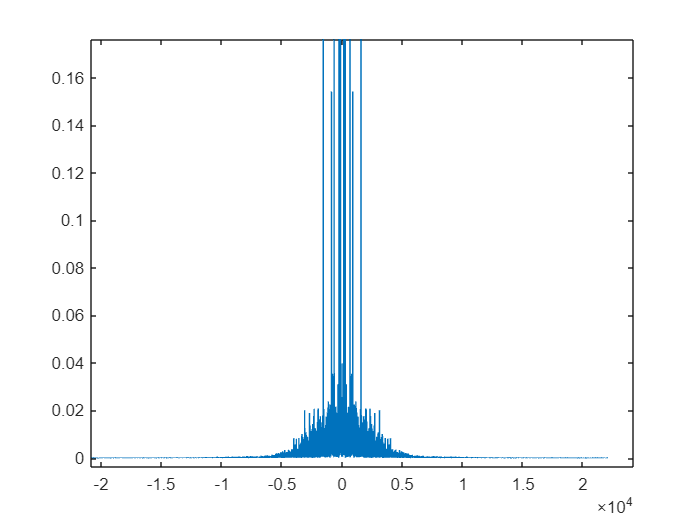

%prueba de una palabra en acorde con frecuencias (oculté)
[W3,fs] = audioread("oculteChord.wav") ;
xw3 = W3(:,1)' ;
fw3 = fft(xw3)/length(xw3);
Xw3 = fftshift(fw3);
omegaw3 = linspace(-fs/2, fs/2, length(Xw3));
time = 0:1/fs:length(xw3)/fs;
time = time(1:end-1) ;
magnitudew3 = abs(Xw3);
figure
plot(omegaw3, magnitudew3)

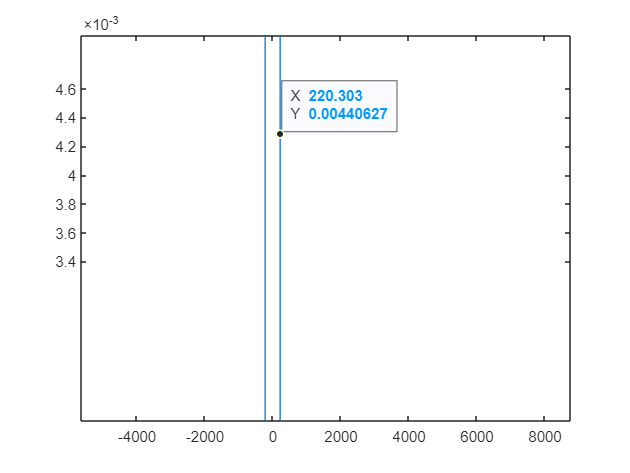

[W3,fs] = audioread("a3-piano-note.wav") ;
xw3 = W3(:,1)' ;
fw3 = fft(xw3)/length(xw3);
Xw3 = fftshift(fw3);
omegaw3 = linspace(-fs/2, fs/2, length(Xw3));
time = 0:1/fs:length(xw3)/fs;
time = time(1:end-1) ;
magnitudew3 = abs(Xw3);
figure
plot(omegaw3, magnitudew3)

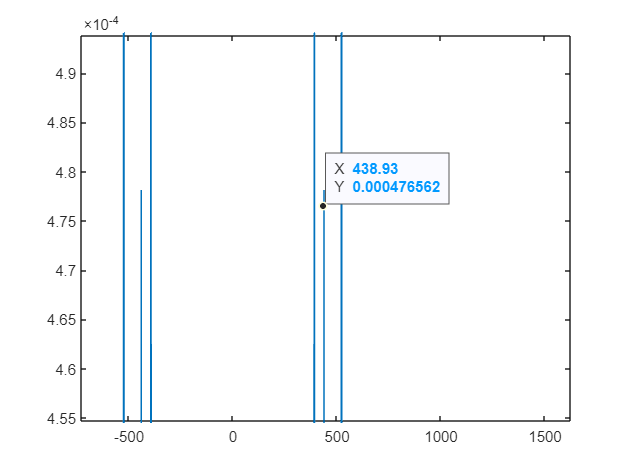

[W3,fs] = audioread("testA3.wav") ;
xw3 = W3(:,1)' ;
fw3 = fft(xw3)/length(xw3);
Xw3 = fftshift(fw3);
omegaw3 = linspace(-fs/2, fs/2, length(Xw3));
time = 0:1/fs:length(xw3)/fs;
time = time(1:end-1) ;
magnitudew3 = abs(Xw3);
figure
plot(omegaw3, magnitudew3)